# Determining MinSpan vectors of COBRA model

## Aarash Bordbar

Sinopia Biosciences, San Diego, CA USA

Reviewed by James T. Yurkovich

## INTRODUCTION

In this tutorial, we show how to calculate MinSpan vectors [1] for a COBRA model. COBRA models are predominantly studied under steady-state conditions, thus the null space of the **S** matrix is of high interest. MinSpan vectors represent the sparsest linear basis of the null space **S **while still maintaining the biological and thermodynamic constraints of the COBRA model (Figure 1). The **S **matrix has dimensions (**m **x **n**) where **m **is the number of metabolites and **n **is the number of reactions. The linear basis of the null space (**N**) has dimensions (**n **x **n-r**) where **r **is the rank of **S**. Thus this algorithm calculates **n-r** vectors that are linearly independent of each other and also are minimal. For further info on MinSpan, it's derivation, implementation, and uses, see Bordbar et al. 2014 [1].

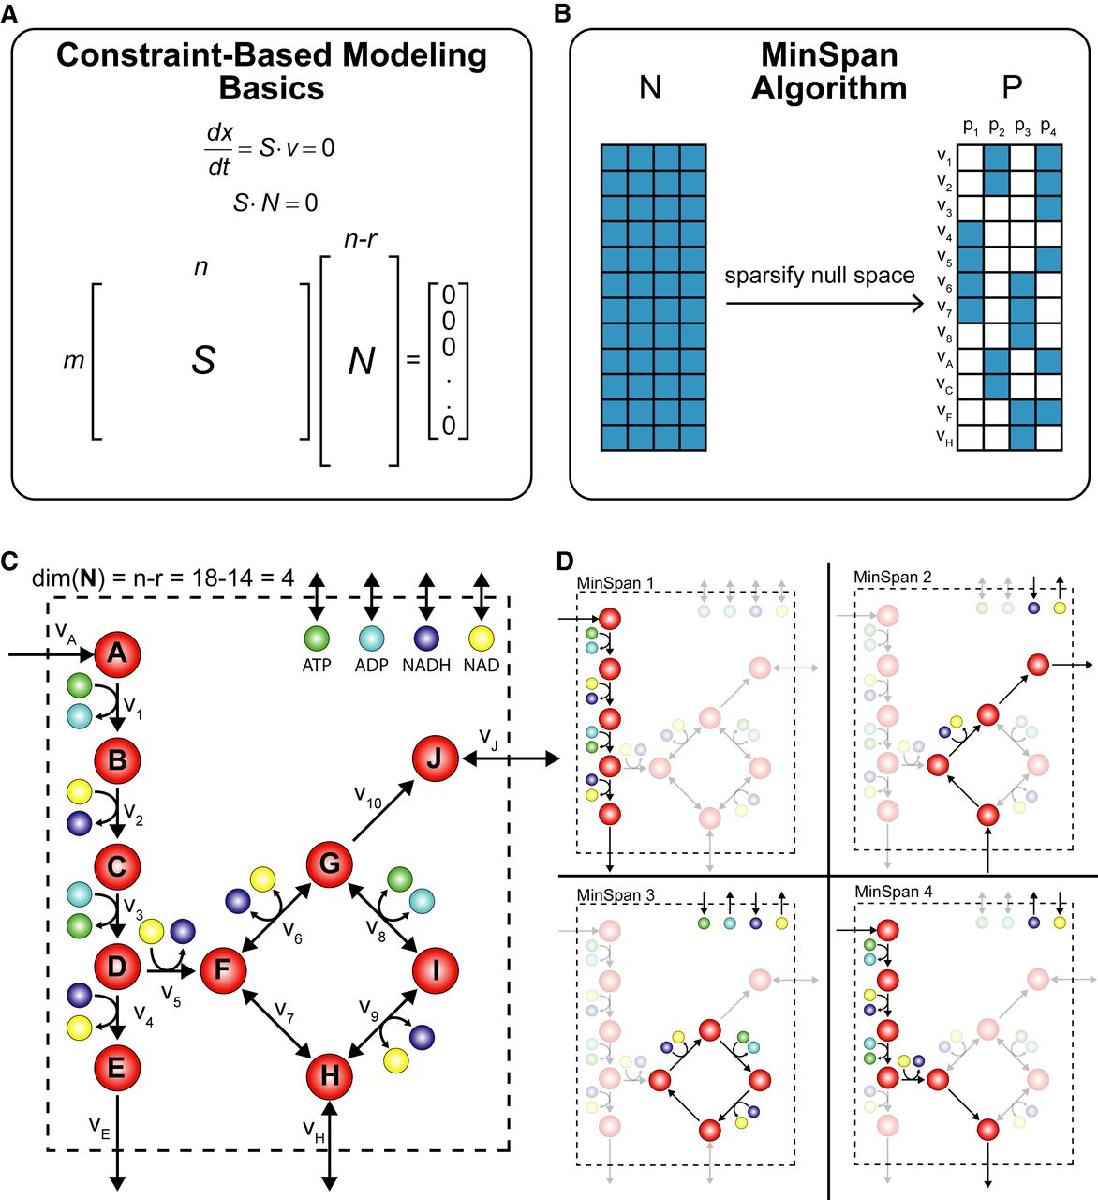

Figure 1 | Overview of the MinSpan algorithm. (A) A metabolic network is mathematically represented as a stoichiometric matrix (**S**). Reaction fluxes (**v**) are determined assuming steady state. All potential flux states lie in the null space (**N**). (B) The MinSpan algorithm determines the shortest, independent pathways of the metabolic network by decomposing the null space of the stoichiometric matrix to form the sparsest basis. (C) A simplified model for glycolysis and the TCA cycle is presented with 14 metabolites, 18 reactions, and a 4-dimensional null space. Reversible reactions are shown. (D) The four pathways calculed by MinSpan for the simplified model are presented, two of which recapitulate glycolysis and the TCA cycle, while the other two represent other possible metabolic pathways. The flux directions of a pathway through reversible reactions are shown as irreversible reactions. 

## MATERIALS

## Equipment Setup

Running the MinSpan algorithm requires the installation of a mixed-integer linear programming (MILP) solver. We have used Gurobi v5+ (http://www.gurobi.com/downloads/download-center) which is freely available for academic use. This tutorial and the algorithm has been rigorously tested and support Gurobi v5+. `detMinSpan` will not work with GLPK; other solvers are untested.

## Implementation

For MinSpan vectors to be calculated, the model must (1) consist of only reactions that are able to carry flux under that particular condition, (2) allow for the trivial solution (**v **= 0) to be feasible, and (3) have the biomass function removed. `detMinSpan` will automatically check and complete the first two modifications, but the biomass must be removed manually.

The algorithm is an iterative pruning of null space basis vectors to the sparsest possible matrix. The problem is NP-hard, meaning that an optimal solution is not guaranteed for large COBRA models; an approximate solution is found by setting a time limit on the MILP calculation.

## Procedure

In this example, we will calculate the MinSpan vectors for the *E. coli* core network. We begin by initializing the COBRA Toolbox in the MATLAB environment and loading the core model.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

load('ecoli_core_model.mat', 'model');

The biomass function is then removed from the model using the COBRA function `removeRxns`.

bmName = {'Biomass_Ecoli_core_w_GAM'};
model = removeRxns(model, bmName);

The MinSpan algorithm takes the model as input and returns a matrix containing the calculated MinSpan vectors (Table 1). 

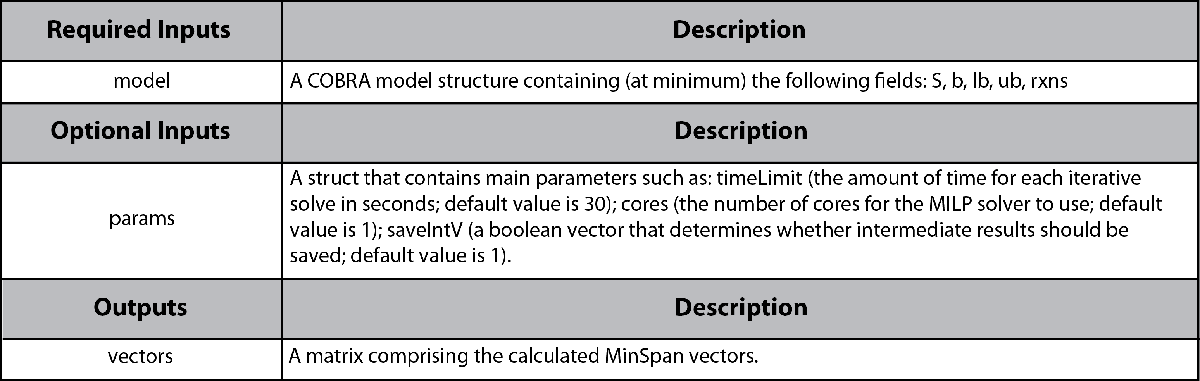

Table 1 | Inputs and outputs of the `detMinSpan` function.

Running the algorithm on the modified *E. coli* core model returns the calculated MinSpans for the network:

minSpanVectors = detMinSpan(model);

Undefined function 'detMinSpan' for input arguments of type 'struct'.

`minSpanVectors` is a matrix that consists of 23 linearly independent vectors. A further description of these vectors is provided and their comparison to Extreme Pathways [2] is provided in the Supplementary Material of Bordbar et al 2014 [1] (Section 1 and Figure S2).

## References

[1] Bordbar A, Nagarajan H, Lewis NE, Latif H, Ebrahim A, Federowicz S, Schellenberger J, Palsson BO. "Minimal metabolic pathway structure is consistent with associated biomolecular interactions" *Mol Syst Biol* **10:**737 (2014).

[2] Schilling CH, Letscher D, Palsson BO. "Theory for the systemic definition of metabolic pathways and their use in interpreting metabolic function from a pathway-oriented perspective. *J Theor Biol ***203:**229-248 (2000).